# **Fall 2017 MATLAB Assignment E: MATHAPPS**

## Math 151-203, Team Pineapple Dream Team,  Marwan Elzarka, Parker Kallman, Stewart Landes, Haley Hefner, 

# *Gilat 6th Edition, Chapter 8*

## *Page 286, Problem 3*

Complete

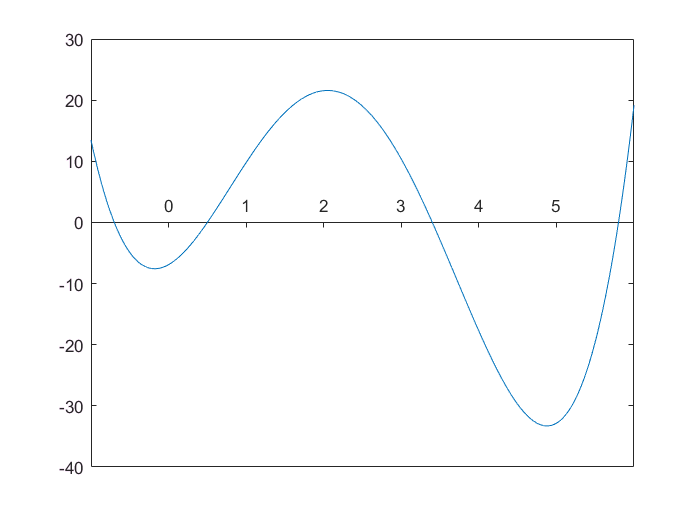

x =[-1:.0001:6];
x1 = [1 .7];
x2 = [1 -.5];
x3 = [1 -3.4];
x4 = [1 -5.8];
p = conv(x1,x2);
p = conv(p, x3);
p = conv(p, x4);
y = polyval(p,x);
plot(x,y);
ax=gca;
ax.XAxisLocation = 'origin';

## *Page 289, Problem 19*

Complete

%Part A
d=@(y) sqrt(4*y.^4-32*y.^3+97*y.^2-136*y+80)

d = function_handle with value:
    @(y)sqrt(4*y.^4-32*y.^3+97*y.^2-136*y+80)


d3 = [4 -32 97 -136 71];
root = roots(d3);
x = @(y) 2.*(y-2).^2+3;
xvals = x(root)

xvals =    5.8921 + 0.0000i
   0.4706 - 1.0053i
   0.4706 + 1.0053i
   4.1668 + 0.0000i


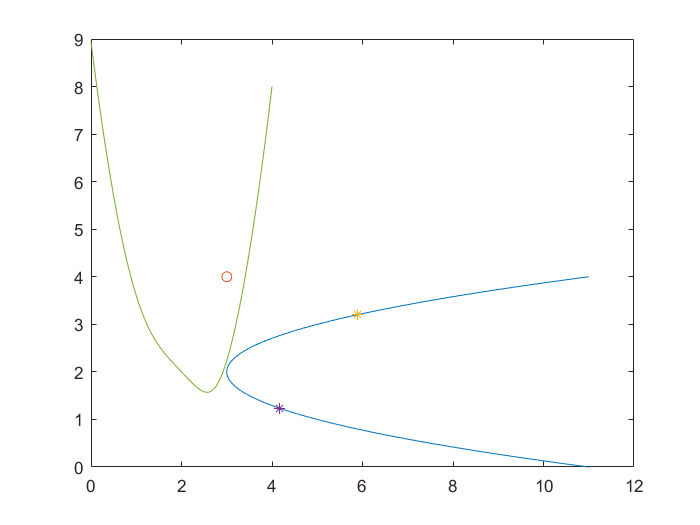

yvals = 0:.01:4;
dvals = d(yvals);
%Part B
plot(yvals,dvals); 

% Part C
fprintf('The distance is 3 at (%f,%f) and (%f,%f).\n',xvals(1),root(1),xvals(4),root(4));

The distance is 3 at (5.892060,3.202510) and (4.166789,1.236197).


% Part D
[ymin,dmin] = fminbnd(d,2,3);
fprintf('The distance is smallest at (%f,%f). The Distance is %f.\n',x(ymin),ymin,dmin);

The distance is smallest at (3.636391,2.564088). The Distance is 1.570617.


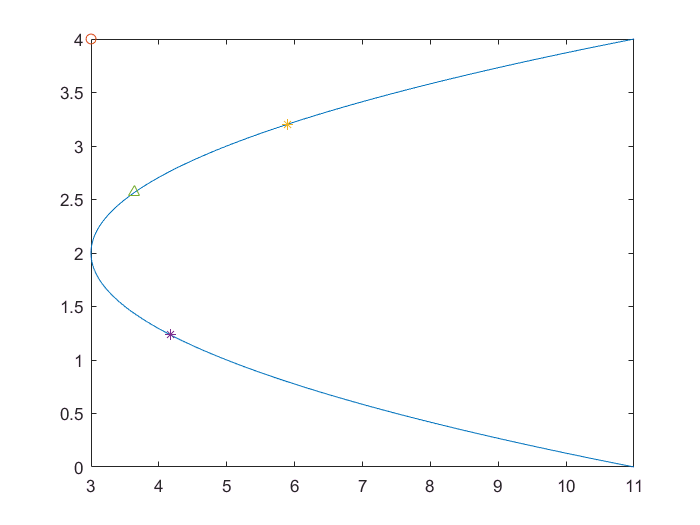

% Part E
figure 
xpoints = x(yvals);
plot(xpoints,yvals);
hold on
plot(3,4,'o');
plot(xvals(1),root(1),'*',xvals(4),root(4),'*');
plot(x(ymin),ymin,'^');

## *Page 290, Problem 22*

Complete

figure
x=[15 45 75 105 135 165];
y=[8.3 19.7 44.4 83.2 127.1 190.9];
p=polyfit(x,y,2);
xa=0:200;
ya=polyval(p,xa);
pop = polyval(p,115);
fprintf('The population in 1915 was %.1f million people.\n',pop);

The population in 1915 was 95.8 million people.


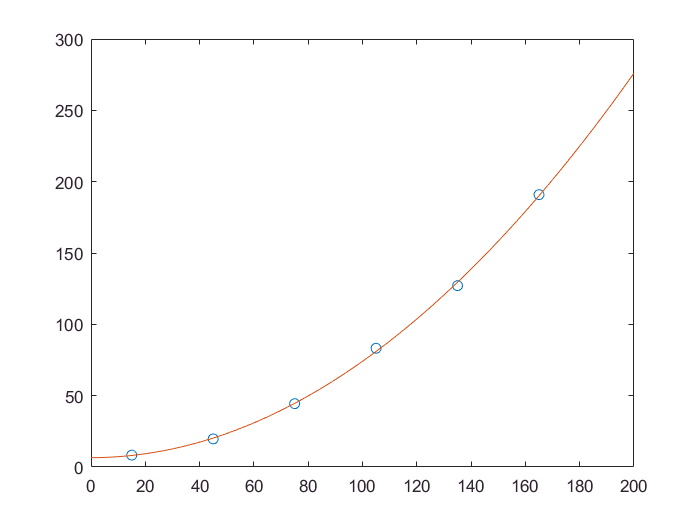

plot(x,y,'o',xa,ya);

fprintf('The equation of the plot is %fx^2 + %fx+%f.\n',p(1),p(2),p(3)); 

The equation of the plot is 0.006722x^2 + 0.003333x+6.537500.


## *Page 292, Problem 28*

Complete 

figure
x = [.4, 2.2 3.1, 5, 6.6, 7.6];
y = [1.7, 10.1 26.9 , 61.2, 158, 398];
s = expofit(x,y);
eq =@(x)  s(2).*exp(x.*s(1));
x1 = .4:.1:7.6;
yvals = eq(x1)

yvals =     2.4515    2.6312    2.8241    3.0312    3.2534    3.4919    3.7479    4.0227    4.3176    4.6341    4.9738    5.3384    5.7298    6.1499    6.6007    7.0846    7.6040    8.1614    8.7597    9.4019   10.0912   10.8310   11.6250   12.4772   13.3919   14.3737   15.4275   16.5584   17.7724   19.0752   20.4737   21.9746   23.5856   25.3146   27.1705   29.1623   31.3002   33.5949   36.0577   38.7011   41.5383   44.5835   47.8520   51.3600   55.1252   59.1665   63.5040   68.1595   73.1563   78.5194


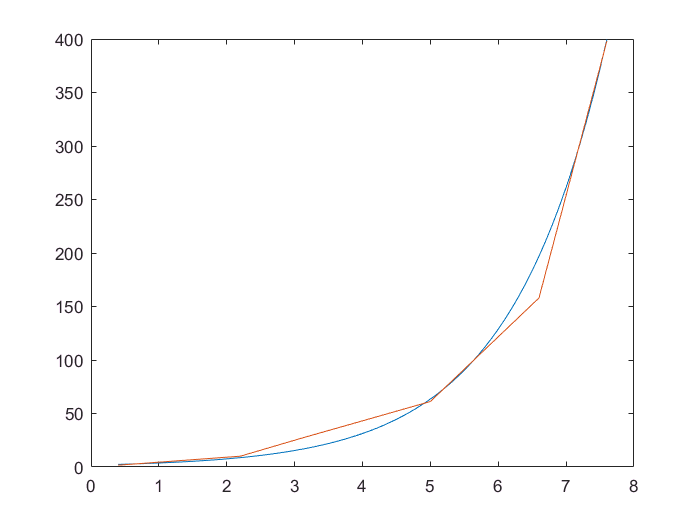

plot(x1,yvals)
hold on
plot(x,y);

## *Page 293, Problem 31*

Complete 

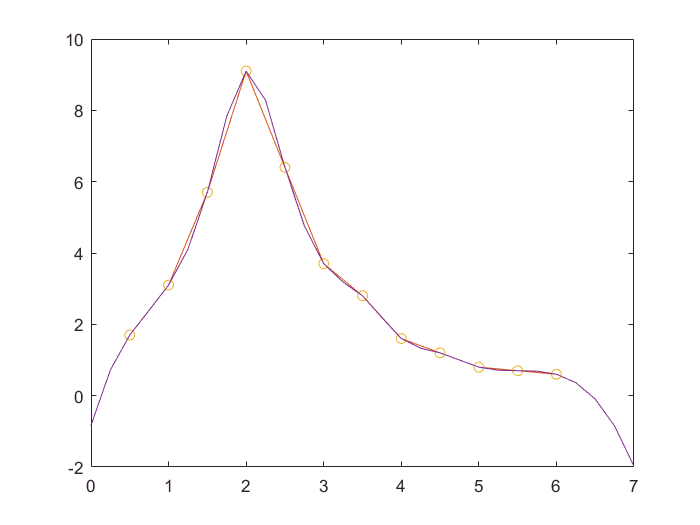

t = .5:.5:6;
C = [1.7,3.1,5.7,9.1,6.4,3.7,2.8,1.6,1.2,.8,.7,.6];
xi=0:.25:7;
figure
yilin= interp1(t,C,xi,'linear');
yispl=interp1(t,C,xi,'spline');
plot(t,C,'o',xi,yilin)
hold on
plot(t,C,'o',xi,yispl)

inter = interp1(t,C,2.25,'linear')

inter = 7.7500

inter2= interp1(t,C,2.25,'spline')

inter2 = 8.2840

# *Gilat 6th Edition, Chapter 9*

## *Page 313, Problem 3*

Complete 

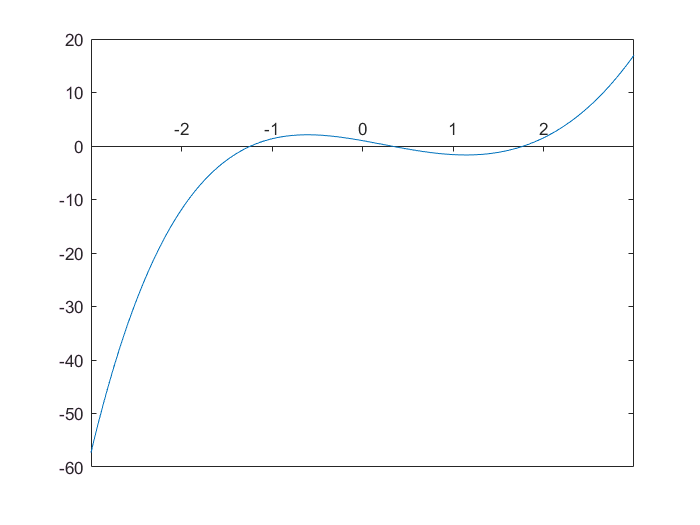

figure
fun = @(x) x.^3-(x.^2.*exp(-.5.*x))-3.*x+1;
xvals = -3:.01:3;
yvals = fun(xvals);
plot(xvals,yvals);
ax=gca;
ax.XAxisLocation = 'origin';

x1 = fzero('x^3-(x^2*exp(-.5*x))-3*x+1',-1);
x2 = fzero('x^3-(x^2*exp(-.5*x))-3*x+1',0);
x3 = fzero('x^3-(x^2*exp(-.5*x))-3*x+1',2);
fprintf('The three zeros are x =%.2f,x= %.2f, and x= %.2f\n',x1,x2,x3);

The three zeros are x =-1.23,x= 0.32, and x= 1.78


## *Page 315, Problem 11*

Complete

[min fmin] = fminbnd('(2+(x-1.45)^2)/(3+3.5*(.8*x^2-.6*x+2))',-50,50)

min = 2.1037

fmin = 0.1350

[max fmax] = fminbnd('-1*(2+(x-1.45)^2)/(3+3.5*(.8*x^2-.6*x+2))',-50,50)

max = -1.6097

fmax = -0.5506

## *Page 316, Problem 18*

Complete

% Lobatto>>>>>>>Simpson
fun1=@(x) (1+.5.*x.^3-x.^2).^(1/4);
a=integral(fun1,0,3);
fun2=@(x) (x.*cos(x)+2.*x.^2)./(exp(x));
b=integral(fun2,0,8);
fprintf('The answer to a is %d and the answer to b is %d',a,b)

The answer to a is 3.056359e+00 and the answer to b is 3.946673e+00

## *Page 317, Problem 24*

Complete

x=@(t) 10.*cos(t)-5.*cos(2*t);
y= @(t) 10.*sin(t)-5*sin(2*t);
difx = @(t) -10.*sin(t)+10.*sin(2.*t);
dify = @(t) 10.*cos(t)-10.*cos(2.*t);
length = @(t) sqrt((-10.*sin(t)+10.*sin(2.*t)).^2+(10.*cos(t)-10.*cos(2.*t)).^2);
integ = integral(length,0,2*pi);
fprintf('The length of the curve is %f.\n',integ);

The length of the curve is 80.000000.


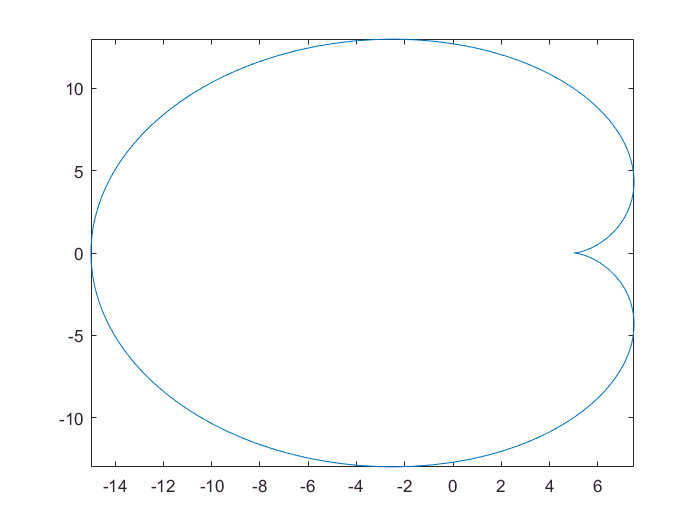

p=linspace(0,2*pi);
fplot(x,y);

## *Page 318, Problem 27*

Complete

z=[0,1,2,3,4,5,6,7,8,9,10,11,12];
r=[0,1.3,1.6,2.4,2.8,3,3.1,3,2.8,2.4,1.65,1.3,0];
S=2*pi*trapz(z,r);
V=pi*trapz(z,r.^2);
fprintf('The surface area of the football is %d square inches and the volume is %d cubic inches.\n',S,V);

The surface area of the football is 1.592787e+02 square inches and the volume is 1.994047e+02 cubic inches.
